clc

clear


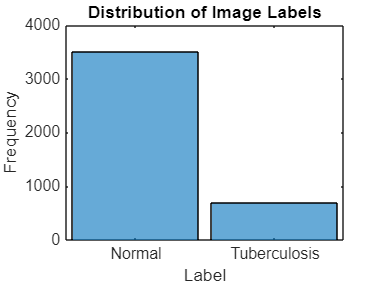


% Load the image datastore
LungImds = imageDatastore("C:\Users\Avrajit\Downloads\TB_Chest_Radiography_Database", "IncludeSubfolders", true, "LabelSource", "foldernames");

% Count number of observations per class
numObs = length(LungImds.Labels);
numObsPerClass = countEachLabel(LungImds);

% Display class distribution histogram
figure;
histogram(LungImds.Labels);
title('Distribution of Image Labels');
xlabel('Label');
ylabel('Frequency');
ylim([0,4000]);
set(gca, 'TickLabelInterpreter', 'none');

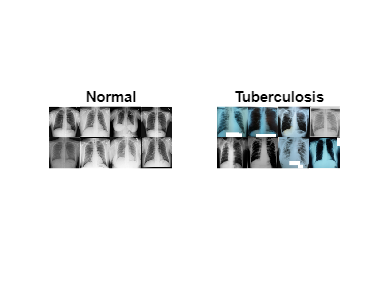


% Example: Show random images from each class
numObsToShow = 8;
subplot(1,2,1)
% Display random Normal class images
class = "Normal";
idxClass = find(LungImds.Labels == class);
idx = randsample(idxClass, numObsToShow);
imshow(imtile(LungImds.Files(idx), 'GridSize', [2 4], 'ThumbnailSize', [100 100]));
title("Normal")
% Display random Tuberculosis class images
subplot(1,2,2)
class = "Tuberculosis";
idxClass = find(LungImds.Labels == class);
idx = randsample(idxClass, numObsToShow);
imshow(imtile(LungImds.Files(idx), 'GridSize', [2 4], 'ThumbnailSize', [100 100]));
title("Tuberculosis")

% Process all images: Compute 2D DCT and filter
numImages = numel(LungImds.Files);
fourierTransforms = cell(numImages, 1);

totalTime = tic;  % Start measuring total time
for i = 1:numImages
    imgTime = tic;  % Start measuring time for each image
    
    % Read image and convert to grayscale if RGB
    img = readimage(LungImds, i);
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    
    % Compute 2D DCT
    F = (dct2(double(img)));
    
    fourierTransforms{i} = abs(F);
    
    % Display time taken for the current image
    fprintf('Time taken for image %d: %.4f seconds\n', i, toc(imgTime));
end

Time taken for image 1: 0.0300 seconds
Time taken for image 2: 0.0166 seconds
Time taken for image 3: 0.0155 seconds
Time taken for image 4: 0.0169 seconds
Time taken for image 5: 0.0208 seconds
Time taken for image 6: 0.0181 seconds
Time taken for image 7: 0.0167 seconds
Time taken for image 8: 0.0160 seconds
Time taken for image 9: 0.0160 seconds
Time taken for image 10: 0.0164 seconds
Time taken for image 11: 0.0163 seconds
Time taken for image 12: 0.0156 seconds
Time taken for image 13: 0.0160 seconds
Time taken for image 14: 0.0159 seconds
Time taken for image 15: 0.0147 seconds
Time taken for image 16: 0.0147 seconds
Time taken for image 17: 0.0145 seconds
Time taken for image 18: 0.0159 seconds
Time taken for image 19: 0.0149 seconds
Time taken for image 20: 0.0177 seconds
Time taken for image 21: 0.0156 seconds
Time taken for image 22: 0.0150 seconds
Time taken for image 23: 0.0156 seconds
Time taken for image 24: 0.0154 seconds
Time taken for image 25: 0.0151 seconds
Time take


% Display total time taken for the entire loop
fprintf('Total time for all images: %.4f seconds\n', toc(totalTime));

Total time for all images: 111.3342 seconds



% Prepare data for neural network input (flatten 2D into 1D)
X = zeros(numImages, numel(fourierTransforms{1}));
for i = 1:numImages
    X(i, :) = fourierTransforms{i}(:)';
end
Y = categorical(LungImds.Labels);

% Split data into training (70%), validation (15%), and testing (15%) sets by preserving class distribution
cv = cvpartition(Y, 'Holdout', 0.3, 'Stratify', true); % 30% holdout for validation + testing
XTrain = X(cv.training, :);
YTrain = Y(cv.training);

% Split the remaining 30% into validation and test sets (50-50 split) while preserving class distribution
XRemain = X(cv.test, :); % The remaining 30% data
YRemain = Y(cv.test);

cv2 = cvpartition(YRemain, 'Holdout', 0.5, 'Stratify', true);
XVal = XRemain(cv2.training, :);
YVal = YRemain(cv2.training);
XTest = XRemain(cv2.test, :);
YTest = YRemain(cv2.test);

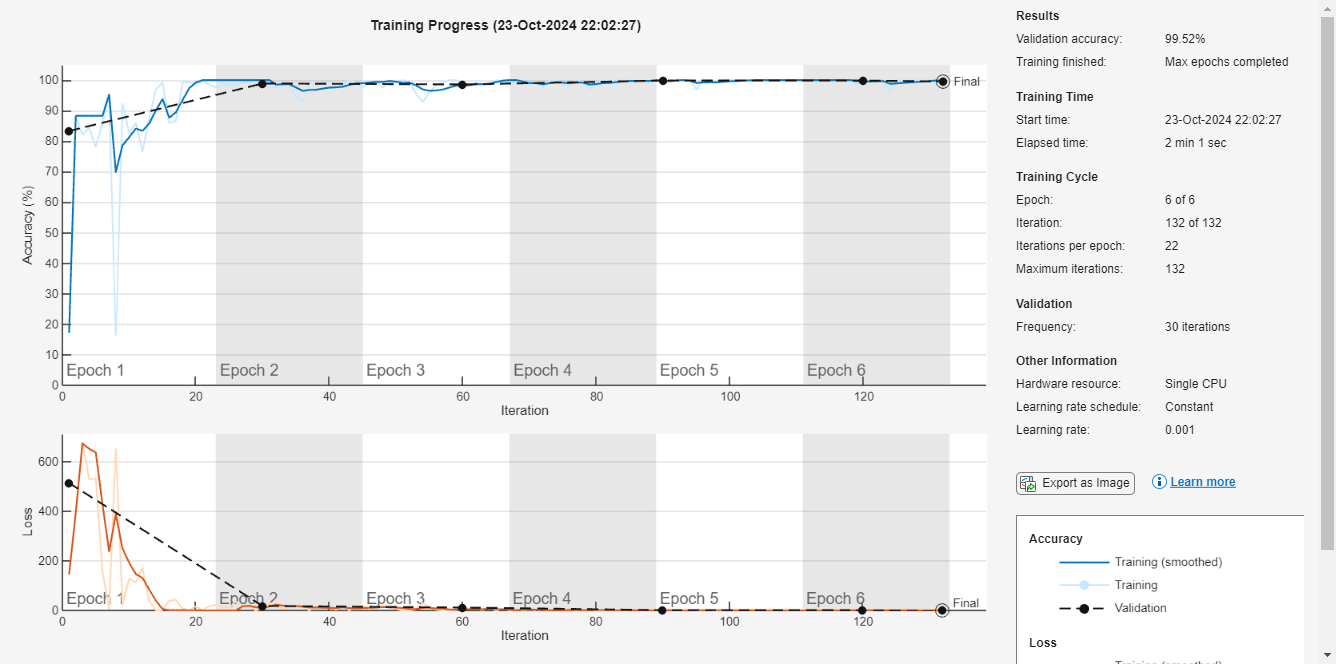


% Define the neural network architecture
layers = [
    featureInputLayer(size(XTrain, 2))
    fullyConnectedLayer(100)
    reluLayer
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(2)  % Adjust for the number of classes
    softmaxLayer
    classificationLayer
];

% Set training options
options = trainingOptions('adam', ...
    'MaxEpochs', 6, ...
    'ValidationData', {XVal, YVal}, ...
    'ValidationFrequency', 30, ...
    'Verbose', false, ...
    'Plots', 'training-progress');  % Optional early stopping

[net, trainingInfo] = trainNetwork(XTrain, YTrain, layers, options);

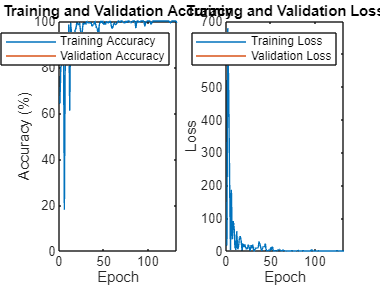

% Extract relevant fields
epochs = 1:length(trainingInfo.TrainingLoss);  % Number of epochs
trainAcc = trainingInfo.TrainingAccuracy;      % Training accuracy for each epoch
valAcc = trainingInfo.ValidationAccuracy;      % Validation accuracy for each epoch
trainLoss = trainingInfo.TrainingLoss;         % Training loss for each epoch
valLoss = trainingInfo.ValidationLoss;         % Validation loss for each epoch

% Plot accuracy (training vs validation)
figure;
subplot(1, 2, 1);
plot(epochs, trainAcc);
hold on;
plot(epochs, valAcc);
xlabel('Epoch');
ylabel('Accuracy (%)');
title('Training and Validation Accuracy');
legend('Training Accuracy', 'Validation Accuracy');
hold off;

% Plot loss (training vs validation)
subplot(1, 2, 2);
plot(epochs, trainLoss);
hold on;
plot(epochs, valLoss);
xlabel('Epoch');
ylabel('Loss');
title('Training and Validation Loss');
legend('Training Loss', 'Validation Loss');
hold off;


% Extract training accuracy and validation accuracy from trainingInfo
trainAcc = trainingInfo.TrainingAccuracy;  % Training accuracy for each epoch
valAcc = trainingInfo.ValidationAccuracy;  % Validation accuracy for each epoch

% Display the training and validation accuracy per epoch
fprintf('Training Accuracy:\n');

Training Accuracy:


disp(trainAcc);

   17.1875   88.2812   82.0312   84.3750   78.1250   85.9375   95.3125   16.4062   92.1875   82.8125   85.9375   76.5625   87.5000   96.8750   99.2188   85.9375   86.7188   99.2188   99.2188   98.4375  100.0000   98.4375   97.6562   99.2188   98.4375   98.4375   99.2188   99.2188  100.0000   99.2188   97.6562   97.6562   99.2188   98.4375   94.5312   92.9688   99.2188   98.4375   99.2188   99.2188   98.4375   98.4375  100.0000   99.2188   97.6562   99.2188   99.2188   97.6562   99.2188   99.2188  100.0000   99.2188   95.3125   92.9688   96.0938   98.4375   99.2188  100.0000  100.0000   98.4375   98.4375   99.2188   98.4375   98.4375  100.0000   99.2188   99.2188   99.2188   99.2188   98.4375   99.2188   97.6562  100.0000  100.0000   98.4375   98.4375  100.0000   99.2188   96.8750   99.2188  100.0000   99.2188  100.0000  100.0000  100.0000   99.2188  100.0000   99.2188  100.0000   99.2188   99.2188  100.0000  100.0000  100.0000   96.8750  100.0000  100.0000   99.2188  100.0000  100.0000


fprintf('Validation Accuracy:\n');

Validation Accuracy:


disp(valAcc);

   83.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   98.8889       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   98.5714       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   99.8413       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN

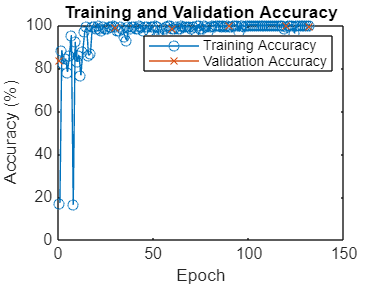


% Plot training and validation accuracy for visual comparison
figure;
plot(1:length(trainAcc), trainAcc, '-o');
hold on;
plot(1:length(valAcc), valAcc, '-x');
xlabel('Epoch');
ylabel('Accuracy (%)');
title('Training and Validation Accuracy');
legend('Training Accuracy', 'Validation Accuracy');
hold off;


% Classify the test data and calculate accuracy
YPred = classify(net, XTest);
accuracy = sum(YPred == YTest) / numel(YTest);
fprintf('Test Accuracy: %.2f%%\n', accuracy * 100);

Test Accuracy: 98.73%


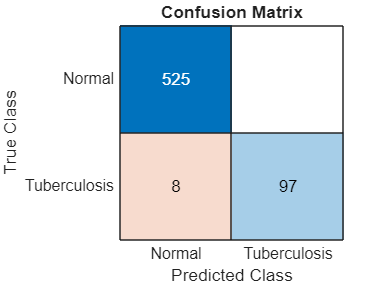


% Display confusion matrix
figure;
ConfMat = confusionmat(YTest, YPred);
confusionchart(YTest, YPred);
title('Confusion Matrix');


% Analyze the network
analyzeNetwork(layers);

% Calculate Precision, Recall, and F1 Score
TP = ConfMat(2, 2); % True Positives (Tuberculosis correctly predicted)
FP = ConfMat(1, 2); % False Positives (Normal misclassified as Tuberculosis)
FN = ConfMat(2, 1); % False Negatives (Tuberculosis misclassified as Normal)
TN = ConfMat(1, 1); % True Negatives (Normal correctly predicted)

precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1_score = 2 * (precision * recall) / (precision + recall);
fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 100.00%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 92.38%


fprintf('F1 Score: %.2f\n', f1_score);

F1 Score: 0.96



% Calculate AUC and ROC curve
[~, scores] = classify(net, XTest);
[Xroc, Yroc, ~, AUC] = perfcurve(YTest, scores(:, 2), 'Tuberculosis');
fprintf('AUC: %.4f\n', AUC);

AUC: 0.9714


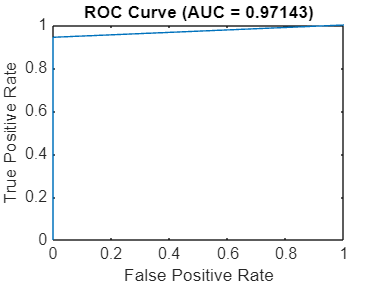


% Plot ROC curve
figure;
plot(Xroc, Yroc);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curve (AUC = ' num2str(AUC) ')']);

specificity=(TN)/(TN+FN)

specificity = 0.9850

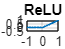

x = -20:0.1:20;              % Define the x values
y_relu = max(0, x);          % Define the ReLU function
y_leaky_relu = max(0.01 * x, x);  % Define the Leaky ReLU function

figure;                      % Create a new figure

% Plot ReLU
          % Create the first subplot
plot(x, y_relu, 'LineWidth', 1);  % Plot the ReLU function
grid on;                    % Turn on grid
                % Remove y-axis ticks
xlim([-1, 1]); 
ylim([-0.5,1])% Set x-axis limits
title('ReLU');              % Title for ReLU subplot

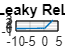


% Plot Leaky ReLU
          % Create the second subplot
plot(x, y_leaky_relu, 'LineWidth', 0.05);  % Plot the Leaky ReLU function
grid on;                    % Turn on grid
                % Remove y-axis ticks
xlim([-10, 5]);
ylim([-1,3])% Set x-axis limits
title('Leaky ReLU');        % Title for Leaky ReLU subplot

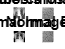

clc;
clear;

% Load the image datastore
LungImds = imageDatastore("C:\Users\Avrajit\Downloads\TB_Chest_Radiography_Database", "IncludeSubfolders", true, "LabelSource", "foldernames");

% Find indices for Pneumonia and Normal classes
TuberculosisIdx = find(LungImds.Labels == "Tuberculosis");
normalIdx = find(LungImds.Labels == "Normal");

% Randomly select one image from each class
pneumoniaSample = randsample(TuberculosisIdx, 1);
normalSample = randsample(normalIdx, 1);

% Read and process the Pneumonia image
pneumoniaImage = readimage(LungImds, pneumoniaSample);
if size(pneumoniaImage, 3) == 3
    pneumoniaImage = rgb2gray(pneumoniaImage);
end
pneumoniaDCT = abs(dct2(double(pneumoniaImage)));

% Read and process the Normal image
normalImage = readimage(LungImds, normalSample);
if size(normalImage, 3) == 3
    normalImage = rgb2gray(normalImage);
end
normalDCT = abs(dct2(double(normalImage)));

% Display the original and DCT images
figure;

% Display Pneumonia image and its DCT
subplot(2, 2, 1);
imshow(pneumoniaImage, []);
title('Tuberculosis Image');

subplot(2, 2, 2);
imshow(log(abs(pneumoniaDCT)), []);
title('Tuberculosis DCT');

% Display Normal image and its DCT
subplot(2, 2, 3);
imshow(normalImage, []);
title('Normal Image');

subplot(2, 2, 4);
imshow(log(abs(normalDCT)), []);
title('Normal DCT');

wordfile = export("tb2.mlx","C:\Users\Avrajit\Downloads\tb2.pdf", ...
    HideCode=true,PageSize="A4",Orientation="Landscape")

wordfile = 'C:\Users\Avrajit\Downloads\tb2.pdf'